# QTRK Circular Deblurring Experiments using MRI Data

clear;clc;close all;
addpath("../../matlab/Circular Deblurring/")
addpath("../")
addpath("../../matlab/tproduct toolbox 2.0 (transform)/")


%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              %takes only first 12 frames   
[m,n,p] = size(X);                      %m1 = 128, n1 = 128, p = 12

%Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m1,n1] = size(h);   

%Building circularly blurred images

Y = zeros(m,n,p);
for i = 1:p
    Y(:,:,i) = blurryimage(X(:,:,i), h, [m,n]);
end


% Add corruption to blurred measurement tensor Y

num_its = 2000; % number of iterations
num_corrupt = 15; % number of corruption
%q = 1-num_corrupt/(m*p*n); % quantile
q = 0.99;
k = 6; %number of corrupted rows

%corruptions are generated from normal distribution
mean_corrupt = 3;
deviation_corrupt = 2;

% Generate random corruption values f
corruption_values = abs(mean_corrupt + deviation_corrupt*randn(num_corrupt, 1));

% Generate k random row indices to corrupt
corrupt_rows = randsample(m, k);

Y_uncorrupted = Y;

% Distribute num_corrupt corruptions uniformly across the k rows
    for i = 1:num_corrupt
        % Select a random row from the chosen rows
        row_idx = corrupt_rows(randsample(k, 1));
        
        % Randomly select indices for the other dimensions
        col_idx = randsample(n, 1);
        depth_idx = randsample(p, 1);
    
        % Apply the corruption value
        Y(row_idx, col_idx, depth_idx) = Y(row_idx, col_idx, depth_idx) + corruption_values(i);
    end

%% Creating a t-linear system corresponding to the deblurring problem

X_reorder = reorder_tensor(X,[m,n,p]);      %dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);
Y_uncorrupted = reorder_tensor(Y_uncorrupted,[m,n,p]);

%Defining the t-linear measurement operator

A = circ_blurring_mxop(h, [m,n,p]);

X0 = zeros(n,p,m);
Xblurry = Y_reorder;
%apply tensor regression technique

%[Z,its] = QTRK_Algorithm(A,Y_reorder,X0,num_its, q); % Adjust q as needed
%Z_qtrk_zero = recover_img(Z,[m,n,p]);
[Z,QTRK_its] = QTRK_Algorithm(A,Y_reorder,X0,num_its, q);
QTRK_errs = zeros(1,num_its+1);
Z_qtrk = recover_img(Z,[m,n,p]);
[Z,mQTRK_its] = mQTRK_Algorithm(A,Y_reorder,X0,num_its, q);
mQTRK_errs = zeros(1,num_its+1);
Z_mqtrk = recover_img(Z,[m,n,p]);

for i = 1:num_its + 1
    QTRK_res = tprod(A,QTRK_its{i}) - Y_uncorrupted;
    QTRK_errs(1,i) = norm(QTRK_res(:))/norm(Y_uncorrupted(:));
    mQTRK_res = tprod(A,mQTRK_its{i}) - Y_uncorrupted;
    mQTRK_errs(1,i) = norm(mQTRK_res(:))/norm(Y_uncorrupted(:));
end

Y_corrupted = recover_img(Y_reorder, [m,n,p]);

%%
%Plotting Convergence Error Plots
%figure(1);
%semilogy(0:its,res_errs,'b-',0:its,res_errs_blurry,'r--','LineWidth',2)
%set(gca,'FontSize',16)
%xlabel('Iterations','FontSize',18) 
%ylabel('Residual Error','FontSize',18) 
%title("Deblurring using QTRK",'FontSize',18)
%legend('zero initialisation', 'blurry initialisation','FontSize',15,'Interpreter','latex','Location','northeast')
%savefig('trgs_deblurring_error_diff_initialization.fig')
%saveas(gcf,'trgs_deblurring_error_diff_initialization.png')
%%

%close all
%figure()
%imshow(Z_qtrk_blurry(:,:,1),[0,1])
%imagesc(Y(:,:,1))

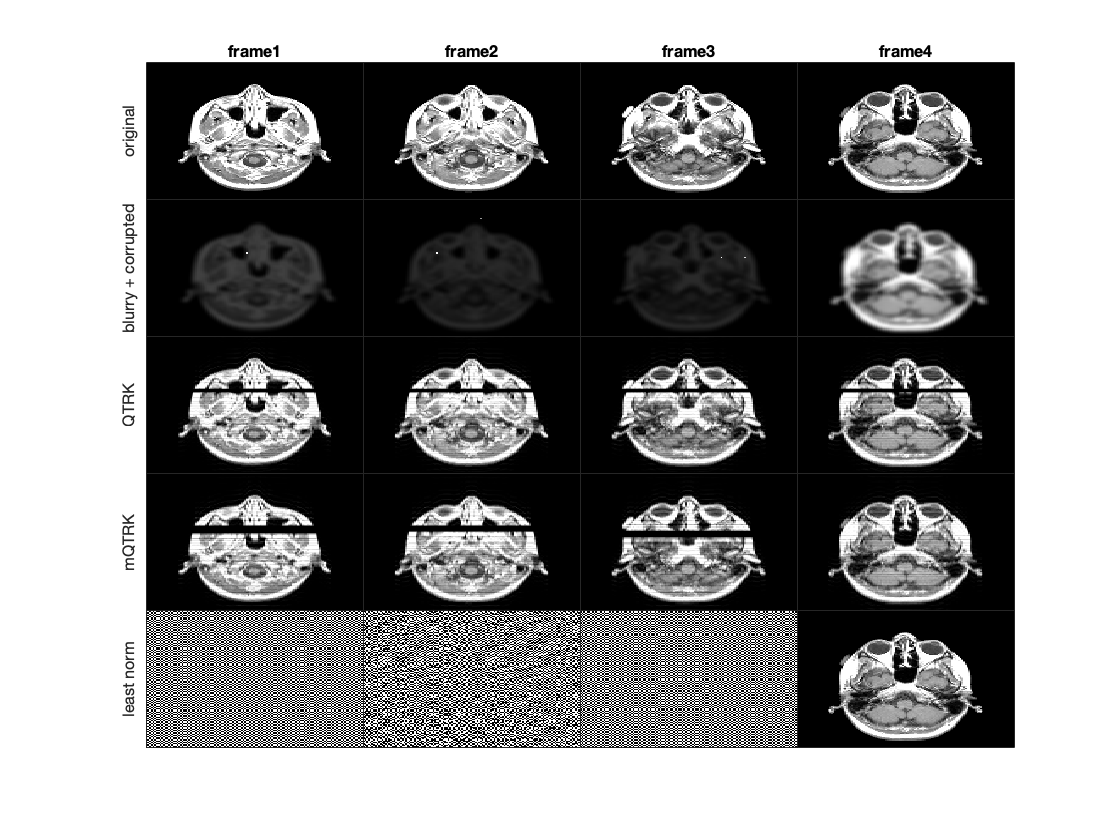

% figure
% it = 4;
% for i = 1:it
%     subplot(4,it,i)
%     imshow(X(:,:,i),[0,1]);axis image off;
%     title(sprintf('original, frame%d',i))
% 
%     subplot(4,it,i+it)
%     imshow(Y_corrupted(:,:,i),[0,1]);axis image off;
%     title(sprintf('blurry + corr , frame%d',i))
% 
%     subplot(4,it,i+2*it)
%     imshow(Z_qtrk_zero(:,:,i),[0,1]);axis image off;
%     title(sprintf('zero init, frame%d',i))
%     
%     subplot(4,it,i+3*it)
%     imshow(Z_qtrk_blurry(:,:,i));axis image off;
%     title(sprintf('blurry init, frame%d',i))    
% end

%savefig('QTRK_deblurring_diff_initialization.fig')
%saveas(gcf,'QTRK_deblurring_diff_initialization.png')
t = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y_corrupted(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry + corrupted",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_qtrk(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("QTRK",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_mqtrk(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("mQTRK",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% for i = 1:4
%     nexttile;
%     imagesc(Z_rand(:,:,i));colormap gray
%     %axis equal
%     %axis tight
%     if i == 1
%         ylabel("rand init",'FontSize',8);
%     end
%     grid off
%     set(gca,'TickLength',[0 0])
%     set(gca,'Yticklabel',[]) 
%     set(gca,'Xticklabel',[])
% end

%calculate least-norm solution
X_ln = tprod(tpinv(A),Y_reorder);
X_ln = recover_img(X_ln,[m,n,p]);
for i = 1:4
    nexttile;
    imagesc(X_ln(:,:,i),[0,1]);colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); %x_width=10cm y_width=15cm

savefig('figs/mQTRK_QTRK_deblurring.fig')
saveas(gcf,'figs/mQTRK_QTRK_deblurring.png')

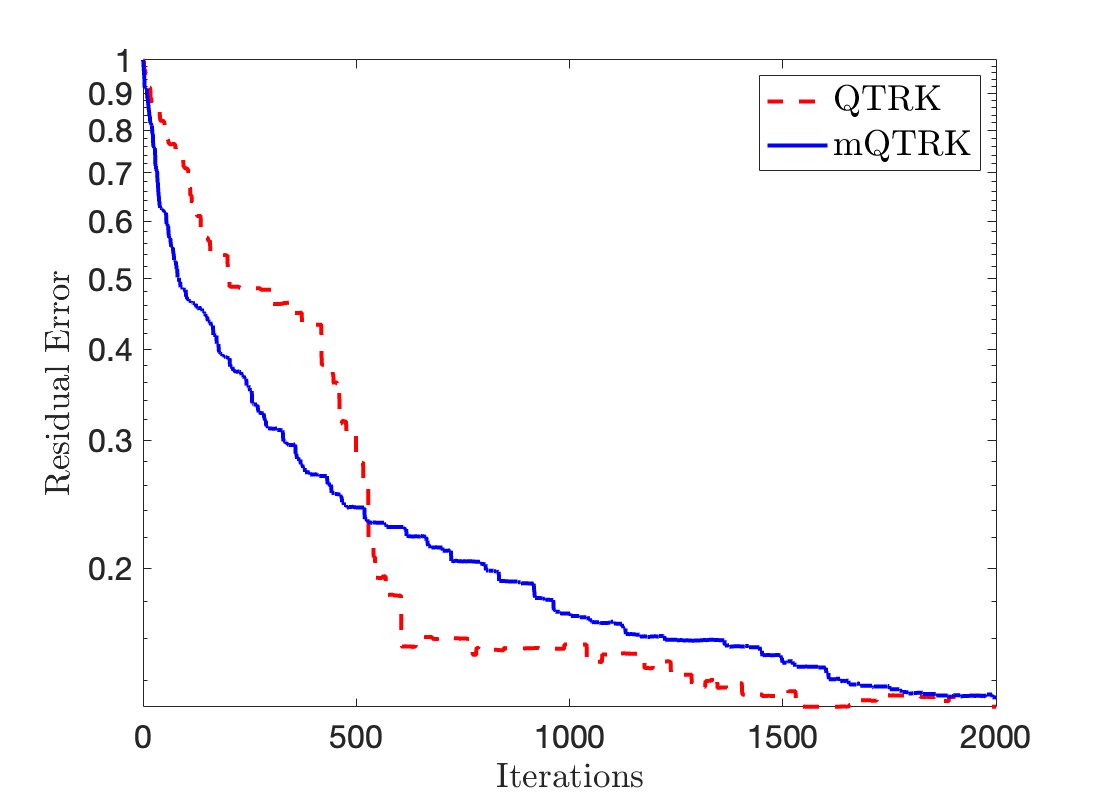

%Plotting Convergence Error Plots

figure(2);
h1 = semilogy(0:num_its,QTRK_errs,'r--','LineWidth',2);
hold on
h2 = semilogy(0:num_its,mQTRK_errs,'b-','LineWidth',2);
hold off
xlabel('Iterations','FontSize',18,'Interpreter','latex') 
ylabel('Residual Error','FontSize',18,'Interpreter','latex') 
legend([h1(1),h2(1)],{'QTRK', 'mQTRK'},'FontSize',18,'Interpreter','latex','Location','northeast')
%title("Deblurring using FacTRK",'FontSize',18)

set(gcf,'position',[10,10,550,400])
set(gca,'FontSize',16)
savefig('figs/mQTRK_QTRK_deblurring_error.fig')
saveas(gca,'figs/mQTRK_QTRK_deblurring_error.png')